# Signal Processing Coursework 

**Signal ID: 69**

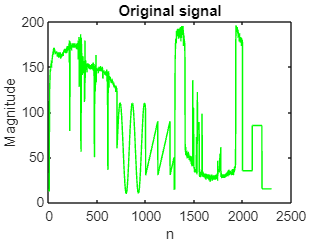

plot(signal,'g');
xlabel("n");
ylabel("Magnitude");
title('Original signal');

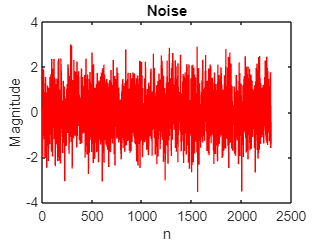

plot(noise,'r');
xlabel("n");
ylabel("Magnitude");
title("Noise");

Determine time domain and frequency domain of the original signal. 

**Adding two signals together **

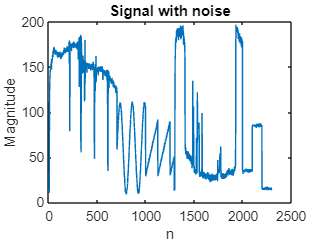

NoisySig= signal+noise;
plot(NoisySig);
ylabel("Magnitude");
xlabel("n");
title('Signal with noise');

### Time domain properties 

Apply difference filter to identify the edges (differences between adjecent values). 

Time domain allows seeing how signal varies accross the time. The in-built diff function calculates differences between adjacent elements of signal. It is clearly visible that there are quite a few edges and many homogenous regions. 

Therefore to identify all edges and divide signal into smaller segments of similar time-domain properties, find function was utilised. 

Important to note, DiffFilter's lenght (number of values) is smaller by one compare to signal's length. It's important to bear that in mind when dividing into segments. 

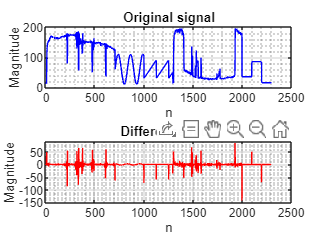

Samples = length(signal); %get number of samples in the signal
DiffFilter = diff(signal); %apply difference filter 
subplot(2,1,1);
plot(signal,"b");
xlabel("n");
ylabel("Magnitude");
grid on;
grid minor;
title("Original signal");
%hold on;
subplot(2,1,2);
plot(DiffFilter, "r");
%hold off;
grid on;
grid minor;
xlabel("n");
ylabel("Magnitude");
title("Difference filter");

%legend("Original signal","DiffFilter signal");

%legend("Position", [0.15008,0.13384,0.25197,0.090599])

#### Edges 

Find function to identify all edges. It looks for all the values within DiffFilter with its absolute values greater than the specified threshold and locates all the spikes. 

**(Double check how to specify the threshold name with lecturer)**

Threshold = 60; %threshold to specify from what values to identify the edges
Spikes = find(abs(DiffFilter)>Threshold);
%plot(Spikes);
%grid on; 
%grid minor;

First rapid spikes observed at 217 

First segment - homogenous region, between 1-217 locations so **first edge 217**

few spikes then up to **704** location - another homogenous region 

then no spikes up to **998**

another region - up to **1292**

then quite a few spikes up to **1581**

then another big spike is **1996**

and then up to the end 

**Remove the DC component to see other values - first and last values of the signal. Just for visualisation **

**can add threshold - higher just to show it's automated **

**Evaluate different lenghts and different number of passees. Just call it few times to a same signal. Show improvement. At some point it gets worse - evaluate it. **

**MSE is not good because one spike and the rest is fine and it does not give you great results. Can add it in conclusions **

## Redundant 

The first rapid change is observed after the 7th location. Then continually all of the diferrences up to location 11 are higher than 15 indicating rapid changes in the signal and non homogenous region. Therefore the first edge is observed at the 8th location.

Then second edge is at the 11th location, as from there onwards up to location 212th ( just one abnormality) 

Regions: 

1-7 - homogenous 

8-11 - non homogenous 

12 - 217 - homogenous

218 - 221 - non homogenous 

 222 - 305 - homogenous 

306 - 316 - non homogenous? 

317 - 330  - homogenous (double check 331

331 - 337 - non homogenous 

338 -  368 - homogenous 

369 - 378 -  non hmogenous 

379 - 468 - homogenous 

469 - 491 - non homogenous 

492 - 607 - homogenous 

609- 613 (another region not sure what type)

614-704 homogenous 

705 - 998 homogenous (decimal start) 

999 - 1124 homogenous (decimals as well)

1125 - 1250 homogenous (decimals)

1251- 1292 homogenous (decimals)

1293-1299 homogenous 

1300 - 1405 (so tiny spikes there initially as the signal is raising in its amplitude) homogenous?

1406 - 1484 homogenous 

1485 - 1494 non homogenous 

1495 - 1529 homogenous 

1530 - 1534 non homogenous 

15335 - 1550 - homogenous 

1551 - 1579 homogenous 

1580 - 1926 homogenous 

1927 - 1996 homogenous 

1997 - 2096 homogenous 

2097 - 2196 homogenous 

2197 - 2296 (end) homogenous 

### Frequency domain properties 

Extract segments from the original signal

%segments ={}; %emply cell array
segment1 = signal(1:217);
segment2 = signal(218:705);
segment3 = signal(706:999);
segment4 = signal(999:1292);
segment5 = signal(1293:1581);
segment6 = signal(1582:1996);
segment7 = signal(1997:end);
% Noisesegment1 = NoisySig(12:217);
% Noisesegment2 = NoisySig(704:999);

**Update the lengths **

FFT - frequency domain properties 

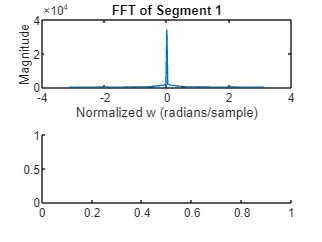

Error using plot
Vectors must be the same length.

numSegments = 7;
%loop to plot all FFTs for each segment 
for segmentIdx = 1:numSegments
    % Construct the segment variable name dynamically 
    segmentVarName = sprintf('segment%d', segmentIdx);
    
    % Perform calculations for the current segment
    [f{segmentIdx}, FT{segmentIdx}] = NiceFFT(eval(segmentVarName));
    [f_noDC{segmentIdx}, FT_noDC{segmentIdx}] = FFT_noDC(eval(segmentVarName));
    figure %start new figure
    subplot(2,1,1) %subplot 1 
    plot(f{segmentIdx},abs(FT{segmentIdx}));
    title(sprintf("FFT of Segment %d", segmentIdx));
    xlabel("Normalized w (radians/sample)");
    ylabel("Magnitude");

    subplot(2,1,2)
    plot(f_noDC{segmentIdx},abs(FT_noDC{segmentIdx}),'g');
    title(sprintf("FFT of Segment %d without DC offset", segmentIdx));
    xlabel("Normalized w (radians/sample)");
    ylabel("Magnitude");
end

The presence of strong frequency components in the signal is indicated by the highest spikes. The prominence of these spikes suggests that certain frequencies in the signal are considerably stronger than others. The dominant frequency component in the signal is close to 0 Hz or DC (direct current) if there is most density around the 0 point of the FFT. A strong low-frequency or DC component in the signal can imply the existence of a significant offset or bias in practical terms. In signal processing, a strong low-frequency component might indicate a trend or baseline in the data.

From FFT can be seen very low frequencies are dominant for all segments so MAF is good as it preserves very low frequencies well and attenuates high frequencies 

DC offset 

DC offset, in the context of signals, refers to a constant voltage or current value that gets added to a signal that otherwise alternates around zero. It's essentially a bias that shifts the entire signal up or down on the vertical axis.

**Causes of DC Offset:**

- Imperfect electronic components:  Electronic components like capacitors can leak a small amount of DC current, introducing an offset.

- Faulty equipment:  Damaged cables or malfunctioning devices can introduce DC offset.

- Signal coupling:  In some cases, unwanted DC voltage from other sources can couple into your signal.

FFT - Redundant

call to  and PlotFFT function 


% % N = length(segment4);
% % FT = fftshift(fft(segment4));
% % index = ceil(-N/2):floor(N/2)-1;
% % f = 2*pi*index/N;
% [f1, FT1] = NiceFFT(segment1);
% [f1_noDC, FT1_noDC] = FFT_noDC(segment1);
% 
% subplot(2,1,1)
% plot(f1, abs(FT1));
% title("FFT of Segment 1");
% xlabel("Normalized w (radians/sample)");
% ylabel("Magnitude");
% subplot(2,1,2)
% plot(f1_noDC, abs(FT1_noDC));
% title("FFT of Segment 1 without DC offset");
% xlabel("Normalized w (radians/sample)");
% ylabel("Magnitude");
% 
% 
% [f2, FT2] = NiceFFT(segment2);
% figure;
% plot(f2, abs(FT2));
% title("FFT of Segment 2");
% xlabel("Normalized w (radians/sample)");
% ylabel("Magnitude");
% 
% [f3, FT3] = NiceFFT(segment3);
% figure;
% plot(f3, abs(FT3));
% title("FFT of Segment 3");
% xlabel("Normalized w (radians/sample)");
% ylabel("Magnitude");
% 
% [f4, FT4] = NiceFFT(segment4);
% figure;
% plot(f4, abs(FT4));
% title("FFT of Segment 4");
% xlabel("Normalized w (radians/sample)");
% ylabel("Magnitude");
% 
% [f5, FT5] = NiceFFT(segment5);
% figure;
% plot(f5, abs(FT5));
% title("FFT of Segment 5");
% xlabel("Normalized w (radians/sample)");
% ylabel("Magnitude");
% 
% [f6, FT6] = NiceFFT(segment6);
% figure;
% plot(f6, abs(FT6));
% title("FFT of Segment 6");
% xlabel("Normalized w (radians/sample)");
% ylabel("Magnitude");
% 
% [f7, FT7] = NiceFFT(segment7);
% figure;
% plot(f7, abs(FT7));
% title("FFT of Segment 7");
% xlabel("Normalized w (radians/sample)");
% ylabel("Magnitude");

The presence of strong frequency components in the signal is indicated by the highest spikes. The prominence of these spikes suggests that certain frequencies in the signal are considerably stronger than others. The dominant frequency component in the signal is close to 0 Hz or DC (direct current) if there is most density around the 0 point of the FFT. A strong low-frequency or DC component in the signal can imply the existence of a significant offset or bias in practical terms. In signal processing, a strong low-frequency component might indicate a trend or baseline in the data.

From FFT can be seen very low frequencies are dominant for all segments so MAF is good as it preserves very low frequencies well and attenuates high frequencies 

#### FFT no DC component - both give the same results - redundant 

% NoDCsegment1 = segment1 - mean(segment1);
% [f1_noDC, FT1_noDC] = NiceFFT(NoDCsegment1);
% figure;
% plot(f1_noDC, abs(FT1_noDC));
% title("FFT of Segment 1 without DC component");
% xlabel("Normalized w (radians/sample)");
% ylabel("Magnitude");
% 
% 
% [f1x, FT1x] = FFT_noDC(segment1);
% figure;
% plot(f1x, abs(FT1x));
% title("FFT of Segment 1 without DC component");
% xlabel("Normalized w (radians/sample)");
% ylabel("Magnitude");

## Feedback 

 Then use the frequency domain properties of the signal segments to determine which length of MAFs should be applied on these segments. You so not have to concatenate the segments back to form the original signal. You should compute the MSE for segments separately and plot segments separately.

**Remove the DC component to see other values - first and last values of the signal. Just for visualisation **

**can add threshold - higher just to show it's automated **

**Evaluate different lenghts and different number of passees. Just call it few times to a same signal. Show improvement. At some point it gets worse - evaluate it. **

**MSE is not good because one spike and the rest is fine and it does not give you great results. Can add it in conclusions **

#### MSE 

#### Redundant

%PlotFFT(segment1,0,'normalisedW');
%FT = fftshift(fft(fftshift(segment1)));
% Nn = length(Noisesegment2);
% FTN = fftshift(fft(Noisesegment2));
%FT1 =fft(segment3);
% indexn = ceil(-Nn/2):floor(Nn/2)-1;
% fn = 2*pi*index/Nn;


% plot(fn,abs(FTN));


%plot(w,FT1);